# 测试（间接法）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]';  % km, km/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 0.1; % s
p.f = 0.1; % N/kg; m/s^2

### 能量最优

@CostEnergy: $\int ||{\bf{u}}||^2 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    0.000000e+00    1.279e+04    4.263e-14
    1      14    9.824538e-02    1.544e+03    1.505e+04    1.113e-02
    2      21    8.491502e-02    1.737e-06    2.167e+04    2.326e-03


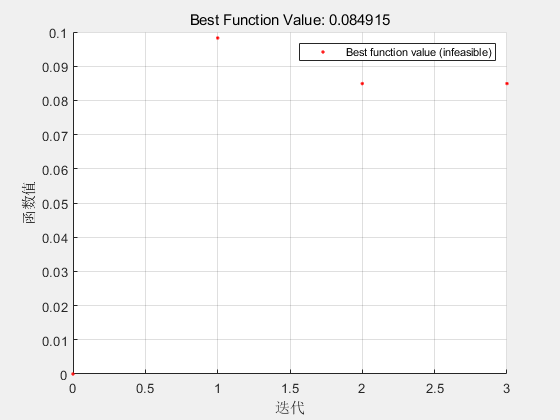


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s,fval,exitflag,output] = IndirOptEnergy(@CwEnergyOpt, x0, xf, tf, p);

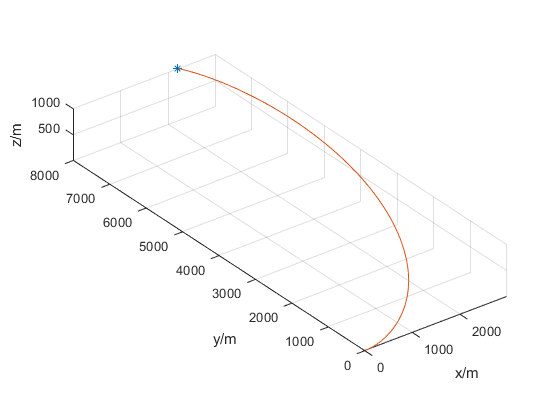

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

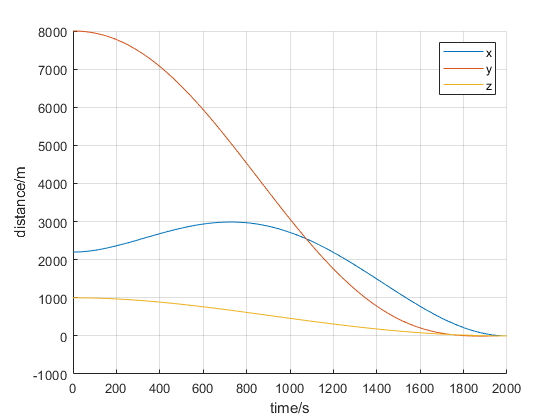

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

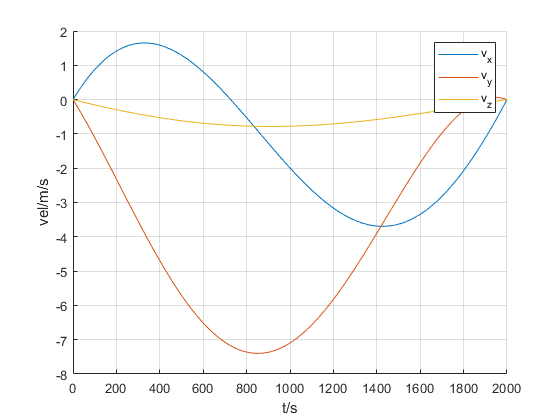

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

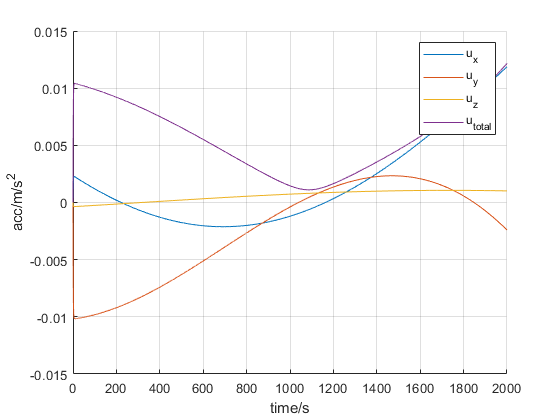

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 燃料最优（同伦）

@CostFuel: $\int \|{\bf{u}}\| \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.453376e-03    1.341e+04    1.110e-16
    1      14    8.198918e-02    4.629e+01    5.846e+04    2.091e+02
    2      21    8.503416e-02    6.369e+00    1.594e+03    4.138e+00
    3      28    8.518323e-02    7.599e-03    2.604e+01    2.299e-01
    4      35    8.518314e-02    1.957e-08    3.510e-03    1.272e-04
    5      42    8.518314e-02    4.621e-11    8.598e-09    1.637e-10

Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the <a h

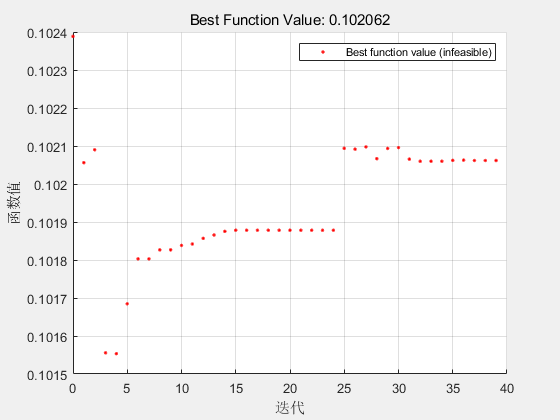


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptFuel(@CwFuelOpt, x0, xf, tf, p);

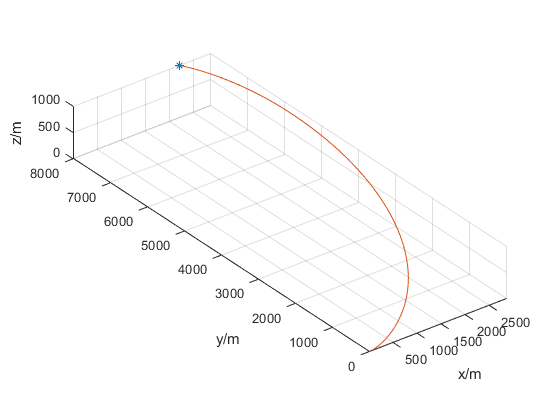

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

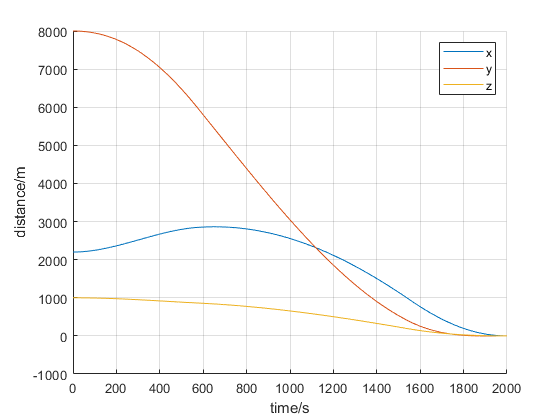

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

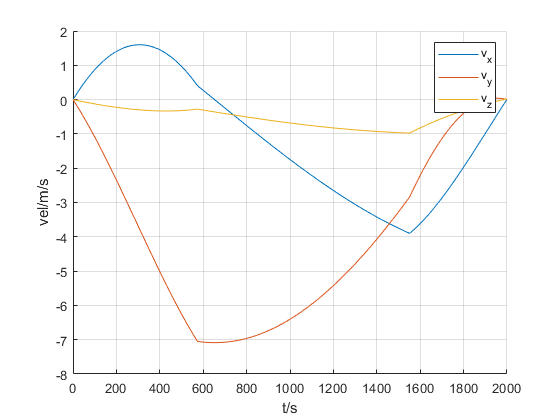

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

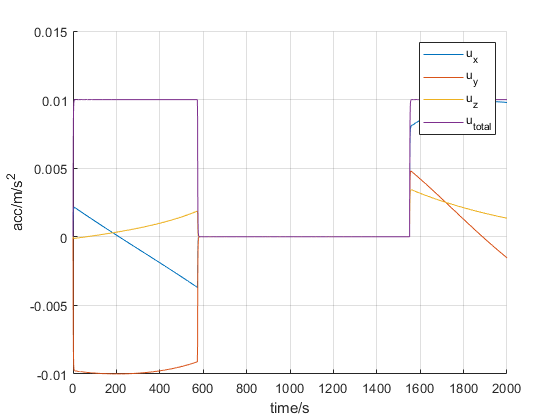

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 时间最优

@CostEnergy: $\int 1 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    1.000000e+03    5.230e+04    1.677e-06
    1      16    9.978844e+02    3.809e+04    1.429e-05    2.117e+00
    2      24    9.860316e+02    4.129e+04    6.139e-05    1.185e+01
    3      32    9.196550e+02    3.796e+04    6.549e-06    6.638e+01
    4      40    8.267279e+02    3.082e+04    4.261e-05    9.293e+01
    5      48    4.253808e+02    8.823e+03    2.630e-06    4.013e+02
    6      59    5.624704e+02    5.756e+03    4.239e-06    1.371e+02
    7      69    5.696221e+02    6.790e+03    2.981e-06    7.152e+00
    8      77    5.624704e+02    6.612e+03    5.170e-06    7.152e+00
    9      91    5.630306e+02    6.617e+03    6.913e-06    5.605e-01
   10      99    5.627103e+02    6.568e+03    1.235e-06    3.819e-01
   11     107    5.589569e+02    6.370e+03    1.434e-05    3.753e+00
   12     122    5.590000e+02    6.385e+03    4

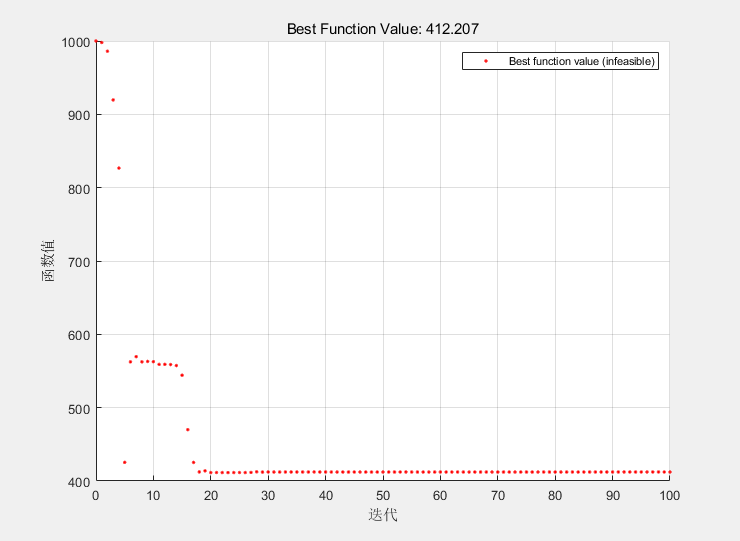


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+02.



% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime2(@CwTimeOpt3, x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwEnergyOpt(t, x, p), x0, xf, tf, p);
[s,fval,exitflag,output] = IndirOptTime3(@(t, x) CwTimeOpt2(t, x, p), x0, xf, tf, p);

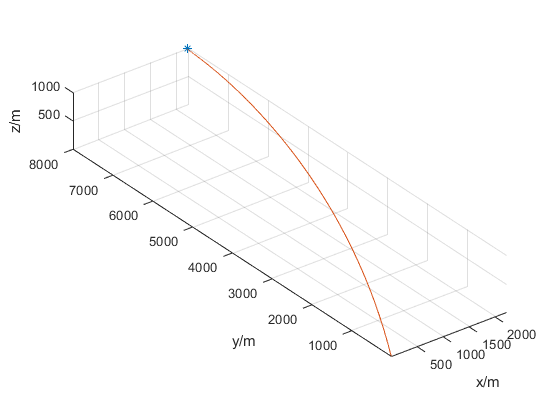

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

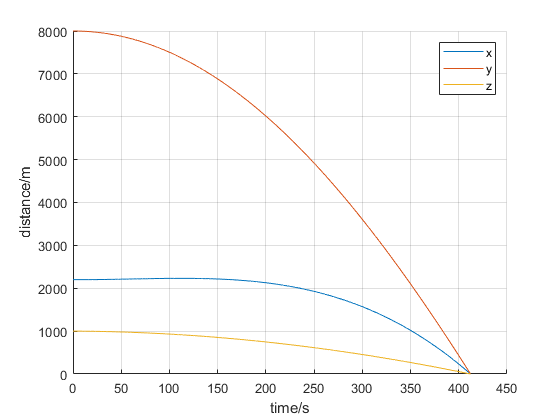

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

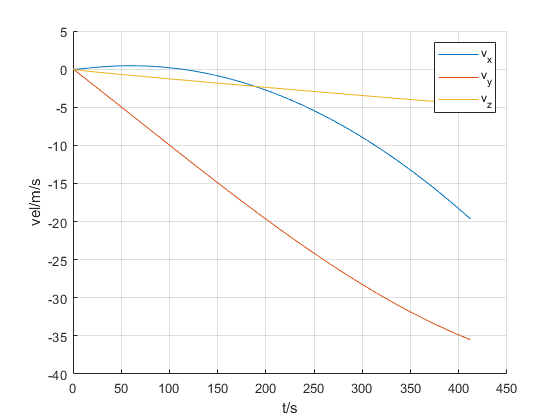

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

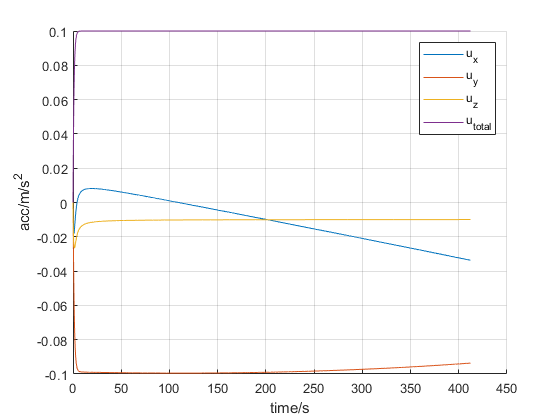

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off